# 02686 - Scientific Computing for Differential Equations - Exam 

## 5 - Classical Runge-Kutta Method 

## Runge-Kutta with fixed Step Size

mu = 3;
mu2 = 20;
x0 = [1.0;1.0];
N = 10000;

[T,X] = ClassicalRungeKuttaFixedStepSize(@VanDerPolTotal,0,mu*5,N,x0,mu);
[T1,X1] = ClassicalRungeKuttaFixedStepSize(@VanDerPolTotal,0,mu2*5,N,x0,mu2);

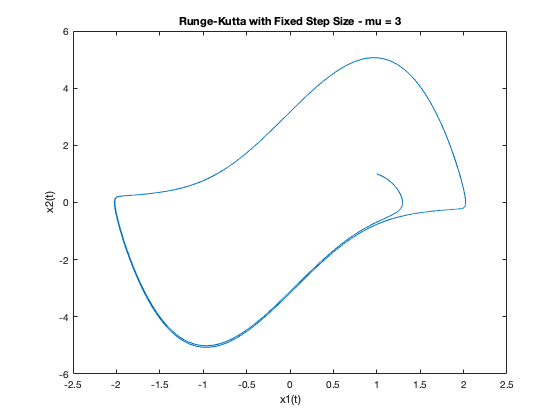

plot(X(:,1),X(:,2))
xlabel('x1(t)')
ylabel('x2(t)')
title('Runge-Kutta with Fixed Step Size - mu = 3')

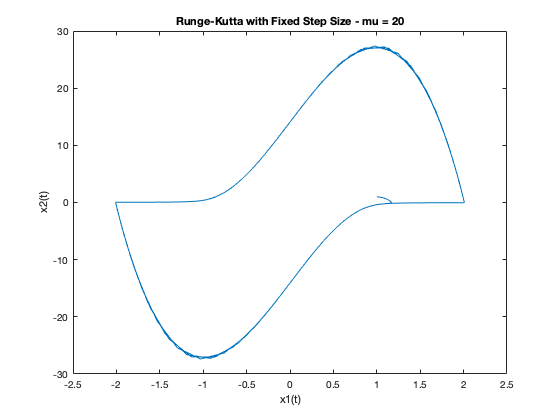


plot(X1(:,1),X1(:,2))
xlabel('x1(t)')
ylabel('x2(t)')
title('Runge-Kutta with Fixed Step Size - mu = 20')

## Runge-Kutta with Adaptative Step Size

mu = 3;
mu2 = 20;
x0 = [1.0;1.0];
N = 10000;

abstol = 1e-7;
reltol = 1e-7;

[T,X,info] = ClassicalRungeKuttaAdaptativeStep(@VanDerPol,0,mu*5,x0,N,abstol,reltol,mu);
[T1,X1,info1] = ClassicalRungeKuttaAdaptativeStep(@VanDerPol,0,mu2*5,x0,N,abstol,reltol,mu2);

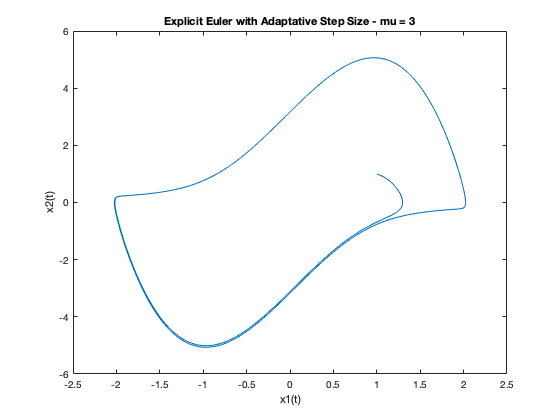

plot(X(:,1),X(:,2))
xlabel('x1(t)')
ylabel('x2(t)')
title('Explicit Euler with Adaptative Step Size - mu = 3')

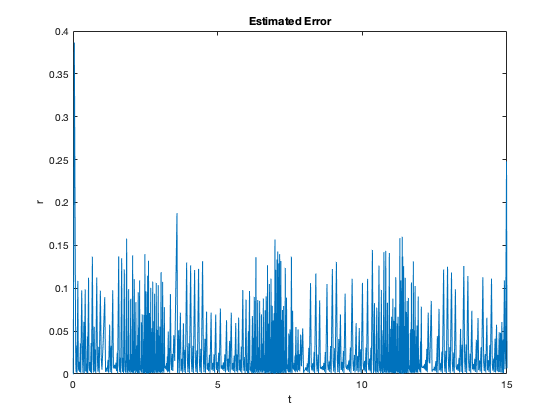


n = length(T);

plot(T(2:n),info.rr)
xlabel("t")
ylabel("r")
title("Estimated Error")

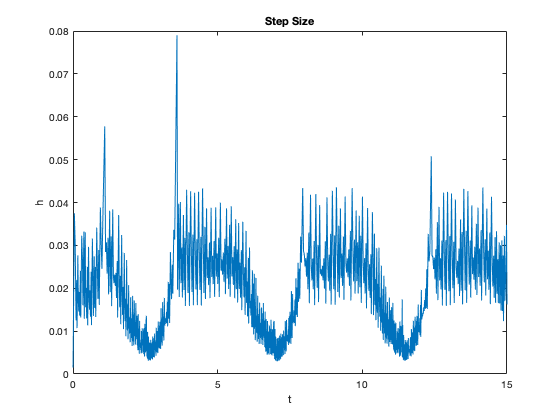


plot(T(2:n),info.hh)
xlabel("t")
ylabel("h")
title("Step Size")

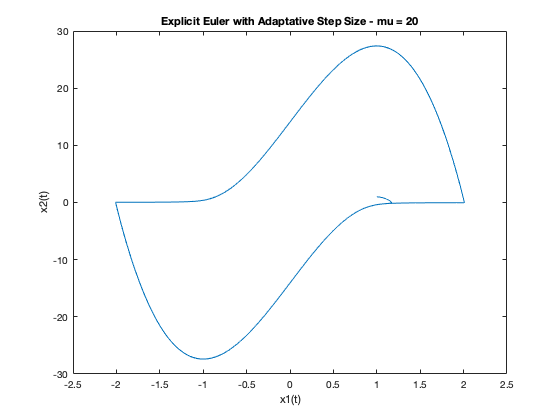

plot(X1(:,1),X1(:,2))
xlabel('x1(t)')
ylabel('x2(t)')
title('Explicit Euler with Adaptative Step Size - mu = 20')

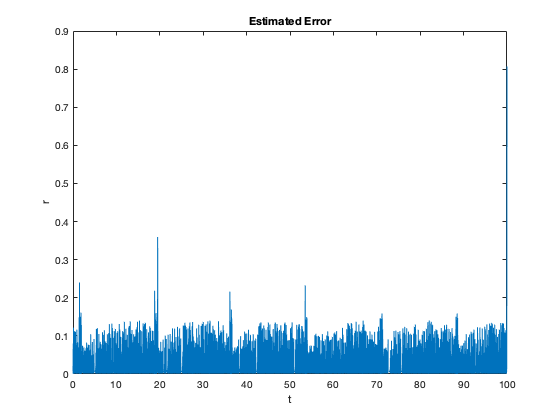


n = length(T1);

plot(T1(2:n),info1.rr)
xlabel("t")
ylabel("r")
title("Estimated Error")

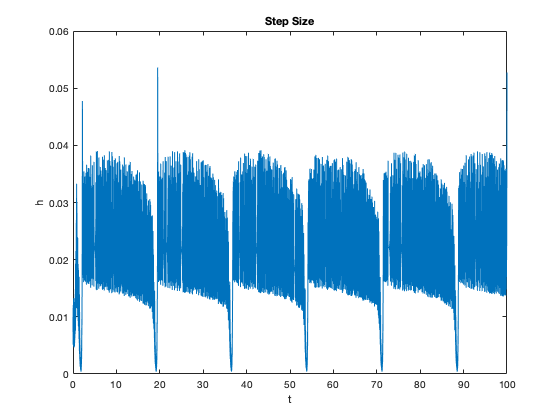


plot(T1(2:n),info1.hh)
xlabel("t")
ylabel("h")
title("Step Size")

## Solver ODE45

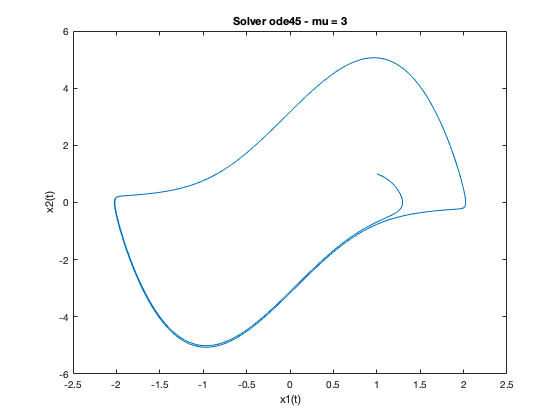

mu = 3;
x0 = [1.0; 1.0];
options = odeset('RelTol',1.0e-6,'AbsTol',1.0e-6);
[T,X]=ode45(@VanDerPol,[0 5*mu],x0,options,mu);

plot(X(:,1),X(:,2))
xlabel('x1(t)')
ylabel('x2(t)')
title('Solver ode45 - mu = 3')

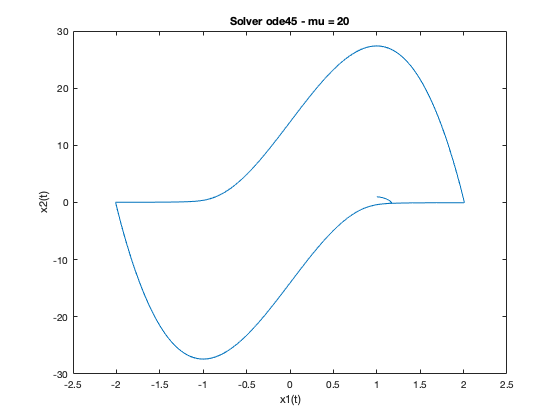

mu = 20;
x0 = [1.0; 1.0];
options = odeset('RelTol',1.0e-6,'AbsTol',1.0e-6);
[T,X]=ode45(@VanDerPol,[0 5*mu],x0,options,mu);

plot(X(:,1),X(:,2))
xlabel('x1(t)')
ylabel('x2(t)')
title('Solver ode45 - mu = 20')

## Solver ODE15s

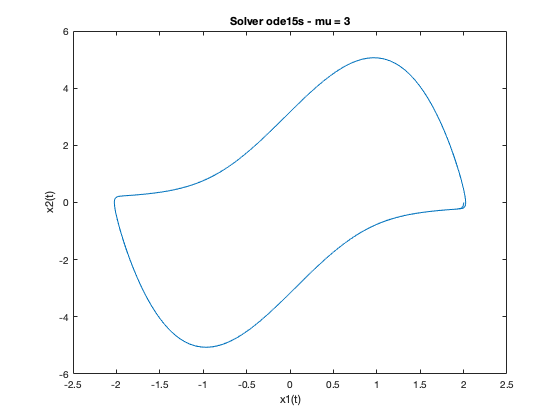

mu = 3;
x0 = [2.0; 0.0];
options = odeset('Jacobian',@JacVanDerPol,'RelTol',1.0e-6,'AbsTol',1.0e-6);
[T,X]=ode15s(@VanDerPol,[0 5*mu],x0,options,mu);

plot(X(:,1),X(:,2))
xlabel('x1(t)')
ylabel('x2(t)')
title('Solver ode15s - mu = 3')

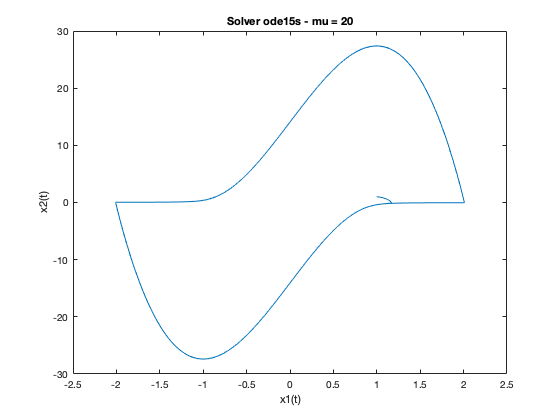

mu = 20;
x0 = [1.0; 1.0];
options = odeset('Jacobian',@JacVanDerPol,'RelTol',1.0e-6,'AbsTol',1.0e-6);
[T,X]=ode15s(@VanDerPol,[0 5*mu],x0,options,mu);

plot(X(:,1),X(:,2))
xlabel('x1(t)')
ylabel('x2(t)')
title('Solver ode15s - mu = 20')